clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[3.82;-1.59;13.96];
u31=[0.0489;0.662;0.748];
r2=[-0.533;4.10;-0.01];
u32=[-0.598;-0.289;0.748];
r3=[7.60;8.81;8.23];
u33=[0.547;0.373;-0.750];
r4=[10.33;2.17;-5.74];
u34=[-0.596;0.287;-0.750];
r5=[14.71;7.86;22.20];
u35=[0.0494;-0.660;-0.750];

axis([0 20 0 20]);
for R3=1:0.2:20 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    hold on
    scatter(R1,R3,'b')
    xlabel('R1'); ylabel('R3');
end

ans =    10.7000    1.0000    1.0062


ans =    10.6500    1.2000    1.0086


ans =    10.6500    1.4000    1.0007


ans =    10.6000    1.6000    1.0011


ans =    10.5500    1.8000    1.0006


ans =    10.4500    2.0000    1.0083


ans =    10.4000    2.2000    1.0061


ans =    10.3500    2.4000    1.0032


ans =    10.2500    2.6000    1.0084


ans =    10.2000    2.8000    1.0040


ans =    10.1000    3.0000    1.0079


ans =    10.0500    3.2000    1.0022


ans =     9.9500    3.4000    1.0048


ans =     9.8500    3.6000    1.0068


ans =     9.7500    3.8000    1.0083


ans =     9.7000    4.0000    1.0006


ans =     9.6000    4.2000    1.0012


ans =     9.5000    4.4000    1.0014


ans =     9.4000    4.6000    1.0014


ans =     9.3000    4.8000    1.0011


ans =     9.2000    5.0000    1.0006


ans =     9.1000    5.2000    1.0000


ans =     8.9500    5.4000    1.0080


ans =     8.8500    5.6000    1.0074


ans =     8.7500    5.8000    1.0069


ans =     8.6500    6.0000    1.0066


ans =     8.5500    6.2000    1.0066


ans =     8.4500    6.4000    1.0069


ans =     8.3500    6.6000    1.0075


ans =     8.2500    6.8000    1.0086


ans =     8.2000    7.0000    1.0012


ans =     8.1000    7.2000    1.0032


ans =     8.0000    7.4000    1.0058


ans =     7.9000    7.6000    1.0090


ans =     7.8500    7.8000    1.0036


ans =     7.7500    8.0000    1.0080


ans =     7.7000    8.2000    1.0036


ans =     7.6000    8.4000    1.0093


ans =     7.5500    8.6000    1.0061


ans =     7.5000    8.8000    1.0034


ans =     7.4500    9.0000    1.0012


ans =     7.3500    9.2000    1.0096


ans =     7.3000    9.4000    1.0086


ans =     7.2500    9.6000    1.0080


ans =     7.2000    9.8000    1.0080


ans =     7.1500   10.0000    1.0086


ans =     7.1000   10.2000    1.0096


ans =     7.1000   10.4000    1.0003


ans =     7.0500   10.6000    1.0021


ans =     7.0000   10.8000    1.0045


ans = 1×3
    6.9500   11.0000    1.0073


ans = 1×3
    6.9000   11.2000    1.0106


ans = 1×3
    6.9000   11.4000    1.0029


ans = 1×3
    6.8500   11.6000    1.0069


ans = 1×3
    6.8000   11.8000    1.0115


ans = 1×3
    6.8000   12.0000    1.0046


ans = 1×3
    6.7500   12.2000    1.0098


ans = 1×3
    6.7500   12.4000    1.0034


ans = 1×3
    6.7000   12.6000    1.0093


ans = 1×3
    6.7000   12.8000    1.0033


ans = 1×3
    6.6500   13.0000    1.0099


ans = 1×3
    6.6500   13.2000    1.0043


ans = 1×3
    6.6000   13.4000    1.0115


ans = 1×3
    6.6000   13.6000    1.0063


ans = 1×3
    6.6000   13.8000    1.0014


ans = 1×3
    6.5500   14.0000    1.0093


ans = 1×3
    6.5500   14.2000    1.0047


ans = 1×3
    6.5500   14.4000    1.0002


ans = 1×3
    6.5000   14.6000    1.0088


ans = 1×3
    6.5000   14.8000    1.0047


ans = 1×3
    6.5000   15.0000    1.0006


ans = 1×3
    6.4500   15.2000    1.0100


ans = 1×3
    6.4500   15.4000    1.0062


ans = 1×3
    6.4500   15.6000    1.0025


ans = 1×3
    6.4000   15.8000    1.0125


ans = 1×3
    6.4000   16.0000    1.0091


ans = 1×3
    6.4000   16.2000    1.0057


ans = 1×3
    6.4000   16.4000    1.0025


ans = 1×3
    6.3500   16.6000    1.0132


ans = 1×3
    6.3500   16.8000    1.0102


ans = 1×3
    6.3500   17.0000    1.0073


ans = 1×3
    6.3500   17.2000    1.0044


ans = 1×3
    6.3500   17.4000    1.0017


ans = 1×3
    6.3000   17.6000    1.0131


ans = 1×3
    6.3000   17.8000    1.0105


ans = 1×3
    6.3000   18.0000    1.0080


ans = 1×3
    6.3000   18.2000    1.0056


ans = 1×3
    6.3000   18.4000    1.0032


ans = 1×3
    6.3000   18.6000    1.0009


ans = 1×3
    6.2500   18.8000    1.0131


ans = 1×3
    6.2500   19.0000    1.0109


ans = 1×3
    6.2500   19.2000    1.0088


ans = 1×3
    6.2500   19.4000    1.0068


ans = 1×3
    6.2500   19.6000    1.0048


ans = 1×3
    6.2500   19.8000    1.0029


ans = 1×3
    6.2500   20.0000    1.0010




for R3=1:0.2:13 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    
    scatter(R1,R3,'r')
    xlabel('R1'); ylabel('R3');
end

ans = 1×3
    9.7500    1.0000    1.0061


ans = 1×3
    9.6000    1.2000    1.0011


ans = 1×3
    9.4000    1.4000    1.0060


ans = 1×3
    9.2500    1.6000    1.0020


ans = 1×3
    9.0500    1.8000    1.0081


ans = 1×3
    8.9000    2.0000    1.0054


ans = 1×3
    8.7500    2.2000    1.0033


ans = 1×3
    8.6000    2.4000    1.0020


ans = 1×3
    8.4500    2.6000    1.0015


ans = 1×3
    8.3000    2.8000    1.0018


ans = 1×3
    8.1500    3.0000    1.0029


ans = 1×3
    8.0000    3.2000    1.0050


ans = 1×3
    7.8500    3.4000    1.0079


ans = 1×3
    7.7500    3.6000    1.0016


ans = 1×3
    7.6000    3.8000    1.0061


ans = 1×3
    7.5000    4.0000    1.0012


ans = 1×3
    7.3500    4.2000    1.0071


ans = 1×3
    7.2500    4.4000    1.0033


ans = 1×3
    7.1000    4.6000    1.0103


ans = 1×3
    7.0000    4.8000    1.0073


ans = 1×3
    6.9000    5.0000    1.0046


ans = 1×3
    6.8000    5.2000    1.0020


ans = 1×3
    6.6500    5.4000    1.0099


ans = 1×3
    6.5500    5.6000    1.0074


ans = 1×3
    6.4500    5.8000    1.0049


ans = 1×3
    6.3500    6.0000    1.0023


ans = 1×3
    6.2000    6.2000    1.0099


ans = 1×3
    6.1000    6.4000    1.0069


ans = 1×3
    6.0000    6.6000    1.0037


ans = 1×3
    5.9000    6.8000    1.0004


ans = 1×3
    5.7500    7.0000    1.0068


ans = 1×3
    5.6500    7.2000    1.0029


ans = 1×3
    5.5000    7.4000    1.0089


ans = 1×3
    5.4000    7.6000    1.0045


ans = 1×3
    5.2500    7.8000    1.0099


ans = 1×3
    5.1500    8.0000    1.0051


ans = 1×3
    5.0500    8.2000    1.0003


ans = 1×3
    4.9000    8.4000    1.0053


ans = 1×3
    4.8000    8.6000    1.0004


ans = 1×3
    4.6500    8.8000    1.0055


ans = 1×3
    4.5500    9.0000    1.0009


ans = 1×3
    4.4000    9.2000    1.0064


ans = 1×3
    4.3000    9.4000    1.0023


ans = 1×3
    4.1500    9.6000    1.0088


ans = 1×3
    4.0500    9.8000    1.0056


ans = 1×3
    3.9500   10.0000    1.0029


ans = 1×3
    3.8500   10.2000    1.0010


ans = 1×3
    3.7000   10.4000    1.0110


ans = 1×3
    3.6000   10.6000    1.0110


ans = 1×3
    3.5500   10.8000    1.0004


ans = 1×3
    3.4500   11.0000    1.0024


ans = 1×3
    3.3500   11.2000    1.0058


ans = 1×3
    3.2500   11.4000    1.0107


ans = 1×3
    3.2000   11.6000    1.0038


ans = 1×3
    3.1000   11.8000    1.0119


ans = 1×3
    3.0500   12.0000    1.0073


ans = 1×3
    3.0000   12.2000    1.0038


ans = 1×3
    2.9500   12.4000    1.0013


ans = 1×3
    2.9000   12.6000    1.0000


ans = 1×3
    2.8000   12.8000    1.0172


ans = 1×3
    2.8000   13.0000    1.0011




for R3=1:0.2:13 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
  
    scatter(R1,R3,'cyan')
    xlabel('R1'); ylabel('R3');
end

ans = 1×3
   15.1000    1.0000    1.0021


ans = 1×3
   15.0500    1.2000    1.0054


ans = 1×3
   15.0500    1.4000    1.0015


ans = 1×3
   15.0000    1.6000    1.0036


ans = 1×3
   14.9500    1.8000    1.0051


ans = 1×3
   14.9000    2.0000    1.0060


ans = 1×3
   14.8500    2.2000    1.0063


ans = 1×3
   14.8000    2.4000    1.0061


ans = 1×3
   14.7500    2.6000    1.0053


ans = 1×3
   14.7000    2.8000    1.0039


ans = 1×3
   14.6500    3.0000    1.0020


ans = 1×3
   14.5500    3.2000    1.0059


ans = 1×3
   14.5000    3.4000    1.0029


ans = 1×3
   14.4000    3.6000    1.0058


ans = 1×3
   14.3500    3.8000    1.0018


ans = 1×3
   14.2500    4.0000    1.0036


ans = 1×3
   14.1500    4.2000    1.0049


ans = 1×3
   14.0500    4.4000    1.0057


ans = 1×3
   13.9500    4.6000    1.0061


ans = 1×3
   13.8500    4.8000    1.0060


ans = 1×3
   13.7500    5.0000    1.0055


ans = 1×3
   13.6500    5.2000    1.0046


ans = 1×3
   13.5500    5.4000    1.0033


ans = 1×3
   13.4500    5.6000    1.0017


ans = 1×3
   13.3000    5.8000    1.0059


ans = 1×3
   13.2000    6.0000    1.0037


ans = 1×3
   13.1000    6.2000    1.0012


ans = 1×3
   12.9500    6.4000    1.0045


ans = 1×3
   12.8500    6.6000    1.0017


ans = 1×3
   12.7000    6.8000    1.0046


ans = 1×3
   12.6000    7.0000    1.0015


ans = 1×3
   12.4500    7.2000    1.0042


ans = 1×3
   12.3500    7.4000    1.0010


ans = 1×3
   12.2000    7.6000    1.0036


ans = 1×3
   12.1000    7.8000    1.0004


ans = 1×3
   11.9500    8.0000    1.0032


ans = 1×3
   11.8500    8.2000    1.0002


ans = 1×3
   11.7000    8.4000    1.0033


ans = 1×3
   11.6000    8.6000    1.0006


ans = 1×3
   11.4500    8.8000    1.0041


ans = 1×3
   11.3500    9.0000    1.0019


ans = 1×3
   11.2000    9.2000    1.0060


ans = 1×3
   11.1000    9.4000    1.0043


ans = 1×3
   11.0000    9.6000    1.0030


ans = 1×3
   10.9000    9.8000    1.0021


ans = 1×3
   10.8000   10.0000    1.0015


ans = 1×3
   10.7000   10.2000    1.0013


ans = 1×3
   10.6000   10.4000    1.0014


ans = 1×3
   10.5000   10.6000    1.0021


ans = 1×3
   10.4000   10.8000    1.0031


ans = 1×3
   10.3000   11.0000    1.0046


ans = 1×3
   10.2000   11.2000    1.0066


ans = 1×3
   10.1500   11.4000    1.0023


ans = 1×3
   10.0500   11.6000    1.0052


ans = 1×3
   10.0000   11.8000    1.0016


ans = 1×3
    9.9000   12.0000    1.0054


ans = 1×3
    9.8500   12.2000    1.0026


ans = 1×3
    9.8000   12.4000    1.0001


ans = 1×3
    9.7000   12.6000    1.0052


ans = 1×3
    9.6500   12.8000    1.0035


ans = 1×3
    9.6000   13.0000    1.0021




for R3=1:0.2:20 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r2,r3,R1,R3,u32,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    [R1,R3,miu2]
   
    scatter(R1,R3,'magenta')
    xlabel('R1'); ylabel('R3');
end

ans = 1×3
    6.2500    1.0000    1.0003


ans = 1×3
    6.2500    1.2000    1.0002


ans = 1×3
    6.2500    1.4000    1.0001


ans = 1×3
    6.2500    1.6000    1.0000


ans = 1×3
    6.2000    1.8000    1.0162


ans = 1×3
    6.2000    2.0000    1.0162


ans = 1×3
    6.2000    2.2000    1.0161


ans = 1×3
    6.2000    2.4000    1.0161


ans = 1×3
    6.2000    2.6000    1.0161


ans = 1×3
    6.2000    2.8000    1.0161


ans = 1×3
    6.2000    3.0000    1.0161


ans = 1×3
    6.2000    3.2000    1.0161


ans = 1×3
    6.2000    3.4000    1.0161


ans = 1×3
    6.2000    3.6000    1.0161


ans = 1×3
    6.2000    3.8000    1.0161


ans = 1×3
    6.2000    4.0000    1.0161


ans = 1×3
    6.2000    4.2000    1.0161


ans = 1×3
    6.2000    4.4000    1.0161


ans = 1×3
    6.2000    4.6000    1.0161


ans = 1×3
    6.2000    4.8000    1.0161


ans = 1×3
    6.2000    5.0000    1.0161


ans = 1×3
    6.2000    5.2000    1.0161


ans = 1×3
    6.2000    5.4000    1.0161


ans = 1×3
    6.2000    5.6000    1.0161


ans = 1×3
    6.2000    5.8000    1.0160


ans = 1×3
    6.2000    6.0000    1.0160


ans = 1×3
    6.2000    6.2000    1.0160


ans = 1×3
    6.2000    6.4000    1.0160


ans = 1×3
    6.2000    6.6000    1.0160


ans = 1×3
    6.2000    6.8000    1.0160


ans = 1×3
    6.2000    7.0000    1.0160


ans = 1×3
    6.2000    7.2000    1.0160


ans = 1×3
    6.2000    7.4000    1.0160


ans = 1×3
    6.2000    7.6000    1.0160


ans = 1×3
    6.2000    7.8000    1.0160


ans = 1×3
    6.2000    8.0000    1.0160


ans = 1×3
    6.2000    8.2000    1.0160


ans = 1×3
    6.2000    8.4000    1.0160


ans = 1×3
    6.2000    8.6000    1.0160


ans = 1×3
    6.2000    8.8000    1.0160


ans = 1×3
    6.2000    9.0000    1.0160


ans = 1×3
    6.2000    9.2000    1.0160


ans = 1×3
    6.2000    9.4000    1.0160


ans = 1×3
    6.2000    9.6000    1.0160


ans = 1×3
    6.2000    9.8000    1.0160


ans = 1×3
    6.2000   10.0000    1.0160


ans = 1×3
    6.2000   10.2000    1.0160


ans = 1×3
    6.2000   10.4000    1.0160


ans = 1×3
    6.2000   10.6000    1.0160


ans = 1×3
    6.2000   10.8000    1.0160


ans = 1×3
    6.2000   11.0000    1.0160


ans = 1×3
    6.2000   11.2000    1.0160


ans = 1×3
    6.2000   11.4000    1.0160


ans = 1×3
    6.2000   11.6000    1.0160


ans = 1×3
    6.2000   11.8000    1.0160


ans = 1×3
    6.2000   12.0000    1.0160


ans = 1×3
    6.2000   12.2000    1.0160


ans = 1×3
    6.2000   12.4000    1.0160


ans = 1×3
    6.2000   12.6000    1.0160


ans = 1×3
    6.2000   12.8000    1.0160


ans = 1×3
    6.2000   13.0000    1.0160


ans = 1×3
    6.2000   13.2000    1.0160


ans = 1×3
    6.2000   13.4000    1.0160


ans = 1×3
    6.2000   13.6000    1.0160


ans = 1×3
    6.2000   13.8000    1.0160


ans = 1×3
    6.2000   14.0000    1.0160


ans = 1×3
    6.2000   14.2000    1.0160


ans = 1×3
    6.2000   14.4000    1.0160


ans = 1×3
    6.2000   14.6000    1.0160


ans = 1×3
    6.2000   14.8000    1.0160


ans = 1×3
    6.2000   15.0000    1.0160


ans = 1×3
    6.2000   15.2000    1.0160


ans = 1×3
    6.2000   15.4000    1.0160


ans = 1×3
    6.2000   15.6000    1.0160


ans = 1×3
    6.2000   15.8000    1.0160


ans = 1×3
    6.2000   16.0000    1.0160


ans = 1×3
    6.2000   16.2000    1.0160


ans = 1×3
    6.2000   16.4000    1.0160


ans = 1×3
    6.2000   16.6000    1.0160


ans = 1×3
    6.2000   16.8000    1.0160


ans = 1×3
    6.2000   17.0000    1.0160


ans = 1×3
    6.2000   17.2000    1.0160


ans = 1×3
    6.2000   17.4000    1.0160


ans = 1×3
    6.2000   17.6000    1.0160


ans = 1×3
    6.2000   17.8000    1.0160


ans = 1×3
    6.2000   18.0000    1.0160


ans = 1×3
    6.2000   18.2000    1.0160


ans = 1×3
    6.2000   18.4000    1.0160


ans = 1×3
    6.2000   18.6000    1.0160


ans = 1×3
    6.2000   18.8000    1.0160


ans = 1×3
    6.2000   19.0000    1.0160


ans = 1×3
    6.2000   19.2000    1.0160


ans = 1×3
    6.2000   19.4000    1.0160


ans = 1×3
    6.2000   19.6000    1.0160


ans = 1×3
    6.2000   19.8000    1.0160


ans = 1×3
    6.2000   20.0000    1.0160



for R3=6:0.2:13 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]

    scatter(R1,R3,'black')
    xlabel('R1'); ylabel('R3');
end

ans = 1×3
   39.6500    6.0000    1.0002


ans = 1×3
   28.5500    6.2000    1.0000


ans = 1×3
   20.2000    6.4000    1.0001


ans = 1×3
   15.8000    6.6000    1.0000


ans = 1×3
   13.3500    6.8000    1.0011


ans = 1×3
   11.8500    7.0000    1.0017


ans = 1×3
   10.8500    7.2000    1.0012


ans = 1×3
   10.1000    7.4000    1.0017


ans = 1×3
    9.5500    7.6000    1.0007


ans = 1×3
    9.1000    7.8000    1.0008


ans = 1×3
    8.7000    8.0000    1.0040


ans = 1×3
    8.4000    8.2000    1.0042


ans = 1×3
    8.1500    8.4000    1.0039


ans = 1×3
    7.9500    8.6000    1.0020


ans = 1×3
    7.7500    8.8000    1.0036


ans = 1×3
    7.6000    9.0000    1.0017


ans = 1×3
    7.4500    9.2000    1.0025


ans = 1×3
    7.3000    9.4000    1.0058


ans = 1×3
    7.2000    9.6000    1.0036


ans = 1×3
    7.1000    9.8000    1.0031


ans = 1×3
    7.0000   10.0000    1.0043


ans = 1×3
    6.9000   10.2000    1.0072


ans = 1×3
    6.8500   10.4000    1.0022


ans = 1×3
    6.7500   10.6000    1.0079


ans = 1×3
    6.7000   10.8000    1.0051


ans = 1×3
    6.6500   11.0000    1.0031


ans = 1×3
    6.6000   11.2000    1.0020


ans = 1×3
    6.5500   11.4000    1.0018


ans = 1×3
    6.5000   11.6000    1.0023


ans = 1×3
    6.4500   11.8000    1.0035


ans = 1×3
    6.4000   12.0000    1.0055


ans = 1×3
    6.3500   12.2000    1.0081


ans = 1×3
    6.3000   12.4000    1.0114


ans = 1×3
    6.3000   12.6000    1.0033


ans = 1×3
    6.2500   12.8000    1.0077


ans = 1×3
    6.2500   13.0000    1.0002



for R1=5:0.2:13 %离心率
    R3=15;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r4,r5,R1,R3,u34,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r4,r5,R1,R3,u34,u35);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r4,r5,R1,R3,u34,u35);
    end
    [R1,R3,miu2]
  
    scatter(R1,R3,'green')
    xlabel('R1'); ylabel('R3');
end

ans = 1×3
    5.0000   19.9000    1.0015


ans = 1×3
    5.2000   19.6000    1.0027


ans = 1×3
    5.4000   19.3500    1.0026


ans = 1×3
    5.6000   19.1500    1.0006


ans = 1×3
    5.8000   18.9500    1.0003


ans = 1×3
    6.0000   18.7500    1.0015


ans = 1×3
    6.2000   18.5500    1.0039


ans = 1×3
    6.4000   18.4000    1.0033


ans = 1×3
    6.6000   18.2500    1.0036


ans = 1×3
    6.8000   18.1500    1.0003


ans = 1×3
    7.0000   18.0000    1.0020


ans = 1×3
    7.2000   17.8500    1.0044


ans = 1×3
    7.4000   17.7500    1.0029


ans = 1×3
    7.6000   17.6500    1.0017


ans = 1×3
    7.8000   17.5500    1.0010


ans = 1×3
    8.0000   17.4500    1.0006


ans = 1×3
    8.2000   17.3500    1.0004


ans = 1×3
    8.4000   17.2500    1.0005


ans = 1×3
    8.6000   17.1500    1.0009


ans = 1×3
    8.8000   17.0500    1.0014


ans = 1×3
    9.0000   16.9500    1.0021


ans = 1×3
    9.2000   16.8500    1.0029


ans = 1×3
    9.4000   16.7500    1.0038


ans = 1×3
    9.6000   16.6500    1.0047


ans = 1×3
    9.8000   16.6000    1.0010


ans = 1×3
   10.0000   16.5000    1.0021


ans = 1×3
   10.2000   16.4000    1.0032


ans = 1×3
   10.4000   16.3000    1.0043


ans = 1×3
   10.6000   16.2500    1.0006


ans = 1×3
   10.8000   16.1500    1.0017


ans = 1×3
   11.0000   16.0500    1.0028


ans = 1×3
   11.2000   15.9500    1.0038


ans = 1×3
   11.4000   15.9000    1.0000


ans = 1×3
   11.6000   15.8000    1.0009


ans = 1×3
   11.8000   15.7000    1.0018


ans = 1×3
   12.0000   15.6000    1.0026


ans = 1×3
   12.2000   15.5000    1.0032


ans = 1×3
   12.4000   15.4000    1.0038


ans = 1×3
   12.6000   15.3000    1.0043


ans = 1×3
   12.8000   15.2500    1.0000


ans = 1×3
   13.0000   15.1500    1.0003


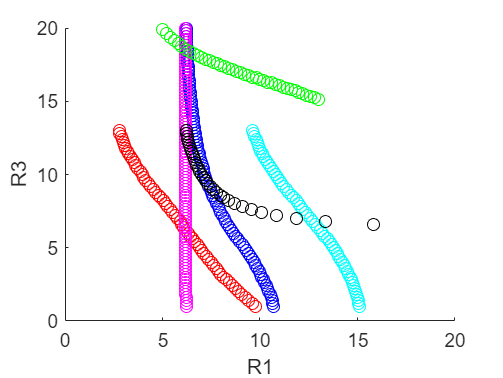

hold off



%cont(rA,rB,R1,R3,uA3,uB3)

%cont(rA,rB,R1,R3,uA3,uB3)
%可能会有其他的椭球重叠

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end

